## Problem 5.28

### Derivation #1: Steady-State Deyst Filter

clear;
F = [0 1 0;-1 -sqrt(2) 0;0 0 -1]

F =          0    1.0000         0
   -1.0000   -1.4142         0
         0         0   -1.0000


G = [sqrt(2) 0;-2 0;0 1]

G =     1.4142         0
   -2.0000         0
         0    1.0000


H = [1 0 1]

H =      1     0     1


Q = eye(2)

Q =      1     0
     0     1


% 0 = FP + PF' + GQG' - (PS2+S3)S1(S2'P+S3')
S1 = inv(H*G*Q*G.'*H.');
S2 = F.'*H.';
S3 = G*Q*G.'*H.';

% Solving CARE
a = F.';
b = S2;
q = G*Q*G.';
r = inv(S1);
s = S3;
e = eye(3);

% Resulting values obtained by solving CARE could be verified by running
% ex_5_28.m. You will observe that state-state value for the error
% variances match the diagonal terms of the Pinf.
[Pinf,~,~] = icare(a,b,q,r,s,e,[])

Pinf =     0.2732   -0.4397   -0.2732
   -0.4397    1.2407    0.4397
   -0.2732    0.4397    0.2732


% you can use the following python code to solve CARE:
% import numpy as np
% from scipy import linalg
% a = np.array([[0,-1,0],[1,-(2**(1/2)),0],[0,0,-1]])
% b = np.array([[0],[1],[-1]])
% s = np.array([[2],[-2 * 2**(1/2)],[1]])
% G = np.array([[2**(1/2), 0],[-2, 0],[0, 1]])
% q = np.matmul(G,G.transpose())
% r = 3
% e = np.identity(3)
% P = linalg.solve_continuous_are(a, b, q, r, e, s)
% P = array([[ 0.27321974, -0.43970231, -0.27321973],
%        [-0.43970231,  1.24071247,  0.43970228],
%        [-0.27321973,  0.43970228,  0.27321975]])
% Pinf = ...
%     [0.27321974, -0.43970231, -0.27321973;
%     -0.43970231,  1.24071247,  0.43970228;
%     -0.27321973,  0.43970228,  0.27321975];

Ainf = (Pinf*F.' + G*Q*G.')*H.'

Ainf =     1.8335
   -2.0274
    1.1665


Winf = Ainf/(H*G*Q*G.'*H.')

Winf =     0.6112
   -0.6758
    0.3888


ydotMatinf = (eye(3) - Winf*H)*F

ydotMatinf =          0    0.3888    0.6112
   -1.0000   -0.7384   -0.6758
         0   -0.3888   -0.6112


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = (s*eye(3) - (eye(3)-Winf*H)*F)\((eye(3)-Winf*H)*F*Winf) + Winf

G =
 
  From input to output...
       0.6112 s^3 + 0.7997 s^2 + 0.1885 s - 1.205e-17
   1:  ----------------------------------------------
           s^3 + 1.35 s^2 + 0.5774 s + 1.649e-08
 
       -0.6758 s^3 - 1.287 s^2 - 0.6112 s + 9.438e-18
   2:  ----------------------------------------------
           s^3 + 1.35 s^2 + 0.5774 s + 1.649e-08
 
       0.3888 s^3 + 0.5499 s^2 + 0.3888 s - 6.414e-18
   3:  ----------------------------------------------
           s^3 + 1.35 s^2 + 0.5774 s + 1.649e-08
 
Continuous-time transfer function.



G0 = G(3)

G0 =
 
  0.3888 s^3 + 0.5499 s^2 + 0.3888 s - 6.414e-18
  ----------------------------------------------
      s^3 + 1.35 s^2 + 0.5774 s + 1.649e-08
 
Continuous-time transfer function.



### Derivation #2: Wiener Filter

clearvars -except G0
k0 = 3;
alpha = sqrt(6)/3 * sqrt(sqrt(3)+1);
beta = 1/sqrt(3);
lambda1 = (2 + sqrt(2))/(1+beta+alpha)

lambda1 = 1.1665

G1 = tf(lambda1/k0 * [1,sqrt(2),1],[1,alpha, beta])

G1 =
 
  0.3888 s^2 + 0.5499 s + 0.3888
  ------------------------------
      s^2 + 1.35 s + 0.5774
 
Continuous-time transfer function.



pole(G0)

ans =   -0.6748 + 0.3493i
  -0.6748 - 0.3493i
  -0.0000 + 0.0000i


pole(G1)

ans =   -0.6748 + 0.3493i
  -0.6748 - 0.3493i


zero(G0)

ans =   -0.7071 + 0.7071i
  -0.7071 - 0.7071i
   0.0000 + 0.0000i


zero(G1)

ans =   -0.7071 + 0.7071i
  -0.7071 - 0.7071i


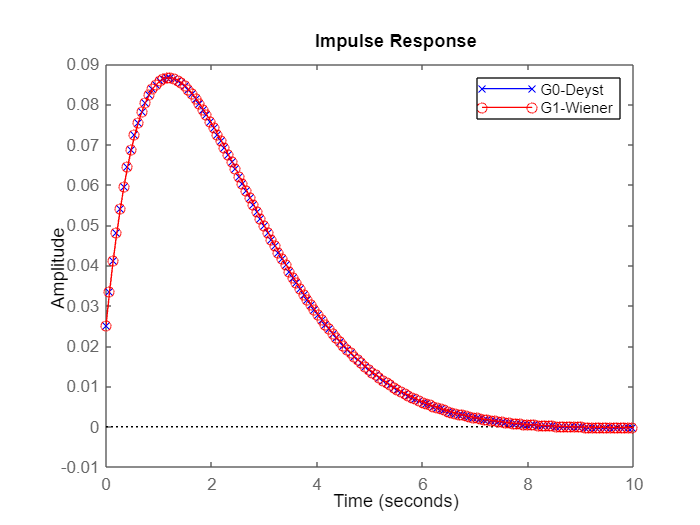

impulse(G0,'b-x',G1,'r-o');
legend({' G0-Deyst',' G1-Wiener'});